Boat Project: Rowan and Jacob

width = 0.0254*2;            % width  (m)
height = 0.06025;            % height (m)
length = 0.07*2;            % length (m)




Npts = 100;                        % number of 1D spatial points (not a design variable; don't change)
xPoints = linspace(-width/2,width/2,Npts); % set of points in the x direction (horizontal)
yPoints = linspace(-length/2,length/2,Npts);
zPoints = linspace(0,height,Npts);      % set of points in the z direction (vertical)

[X, Y, Z] = meshgrid(xPoints,yPoints, zPoints); % create the meshgrid

P = [X(:)'; Y(:)'; Z(:)']; 

a = [];
insideBoat = zeros(size(P(1,:)));



for i = 1:1:Npts
    %get the height of the parabola section using sheer plane equation for
    %current "slice" / section of boat
    sheer_plane_height = sheer_plane_function(P(2,i));
    %get the width of the parabola section
    water_plane_width = hull_plane_function(P(2,i));
    %compute parabola "A" term
    ellipse_width = water_plane_width;
    ellipse_height = height - sheer_plane_height;
    
    %y = a(x-h)^2+k
    
    insideSlice = (P(2,:) == yPoints(i));
    
    t2 = (ellipse_height^2);
    t1 = -(t2) .* (P(1,:).^2);
    t3 = (ellipse_width^2);
    
    Z_bottom = -1 * sqrt((t1/t3) + t2) + height;
    
    %Z_bottom = parabola_width.*(P(1,:)).^2 + sheer_plane_height;
    Z_top = height;
    
    
    insideSection = (P(3,:) > Z_bottom) & (P(3,:) < Z_top);
    %scatter3(P(1,insideSection&insideSlice), P(2,insideSection&insideSlice), P(3,insideSection&insideSlice), ".k");
    insideBoat = insideBoat + (insideSection&insideSlice);
    

    

    
end
insideBoat = insideBoat > 0;

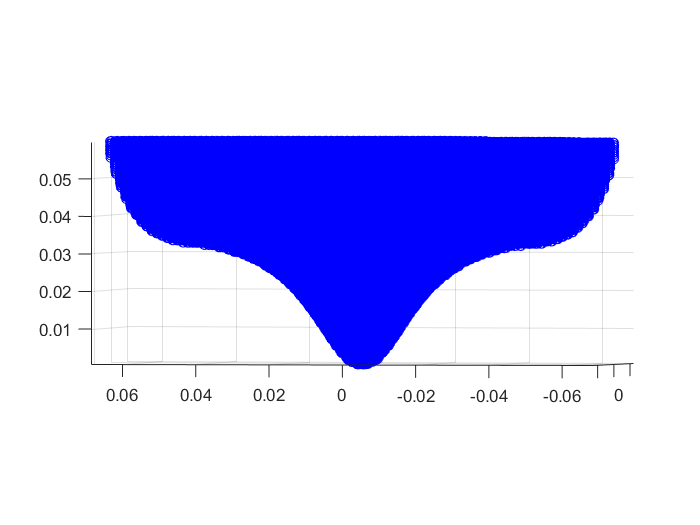


clf

scatter3(P(1,insideBoat), P(2,insideBoat), P(3,insideBoat), 'b')
axis equal

%function for the depth of the boar as viewd from the side: this is the
%crazy witch function thing


function res = sheer_plane_function(x)
res = zeros(size(x));
    if x < -0.04185 || x > 0.04185
        res = res + (1E10 .* x .^ 10) + 0.032;
    end
    if x >= -0.04185 && x <= 0.04185
        res = res + ((-1 * ((0.037^3.5) / (x.^2 + 0.037^(2.5)))) + 0.037);
    end  
end

%fucntion for width of boat as viewd from above
function res = hull_plane_function(x)
res = -5.17*(x^2) + 0.0254;
end
